CAD representation

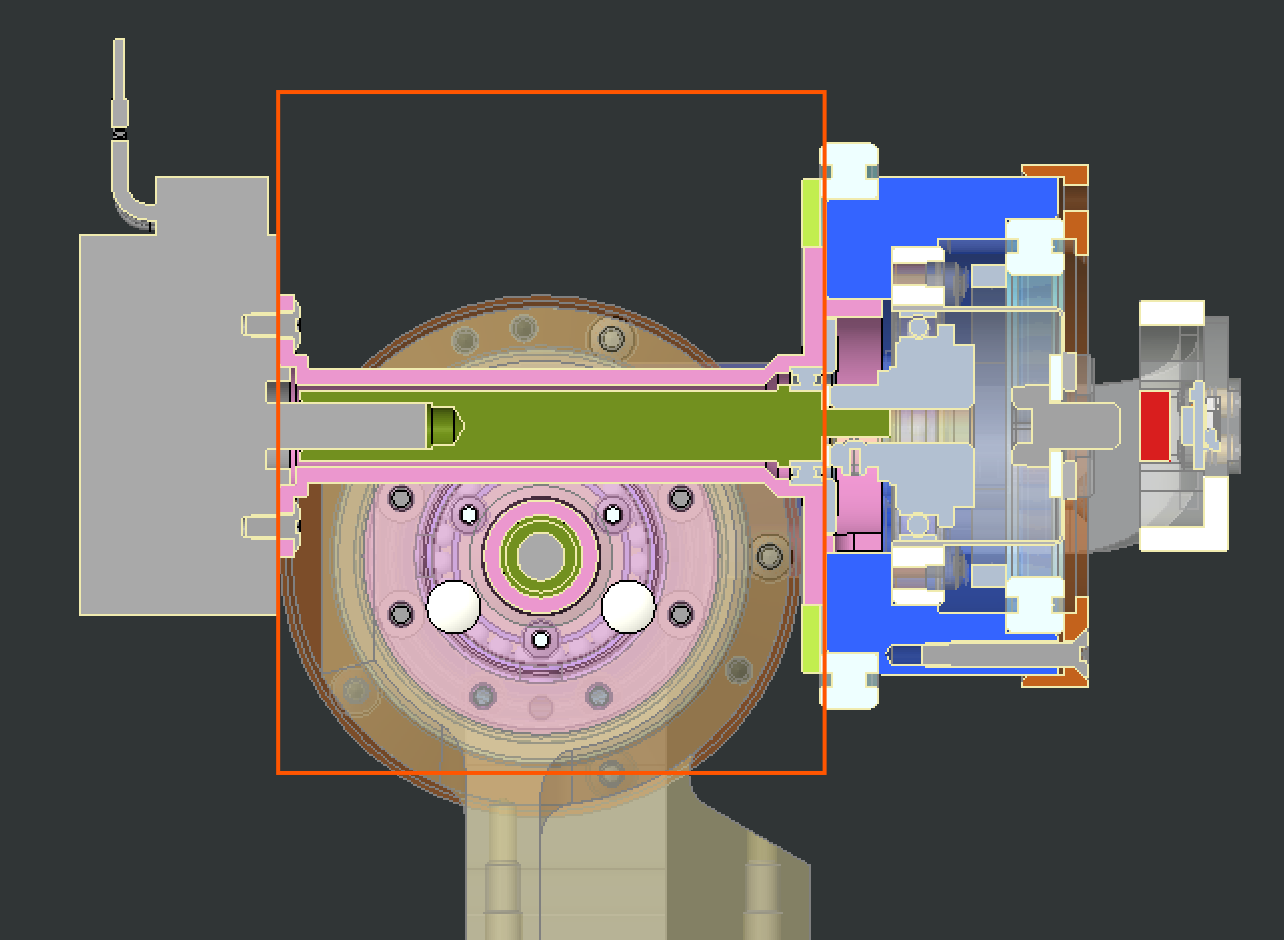

Beam model

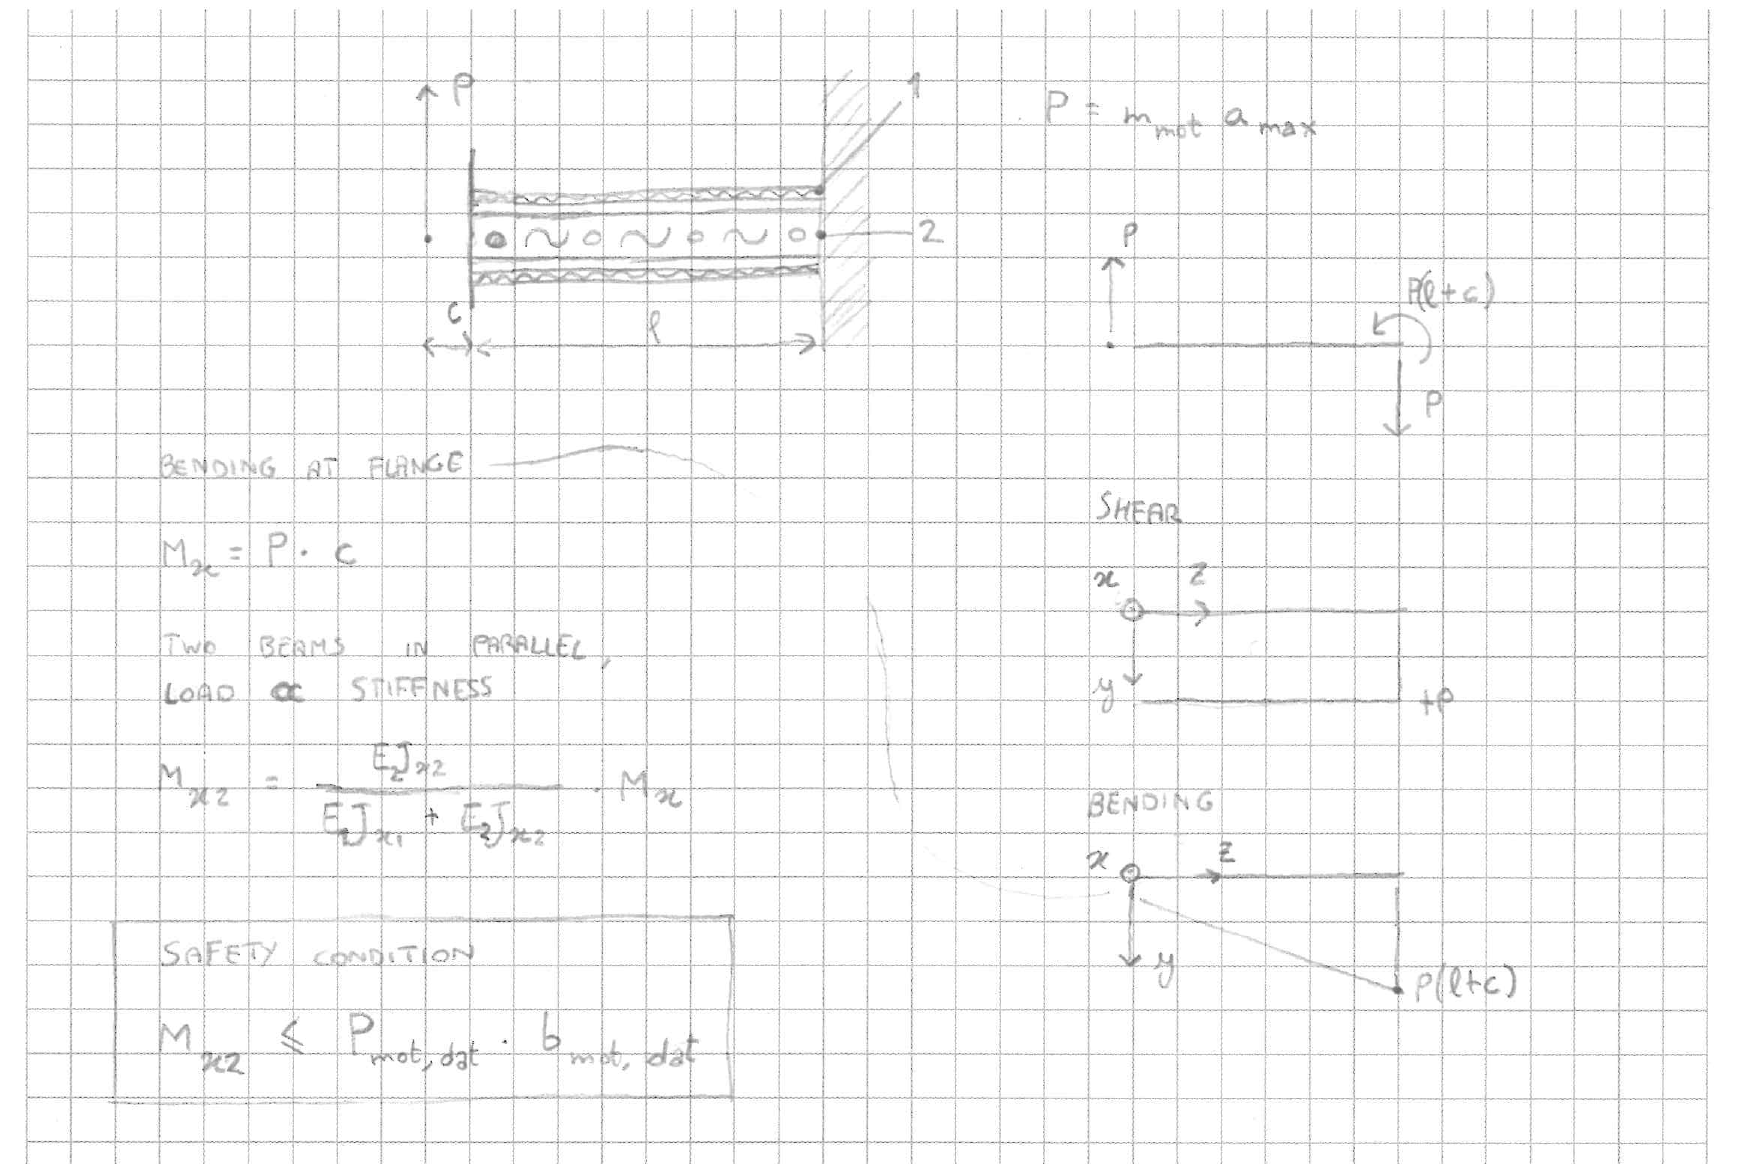

Faulhaber **Series 3216 ... BXT H** datasheet:

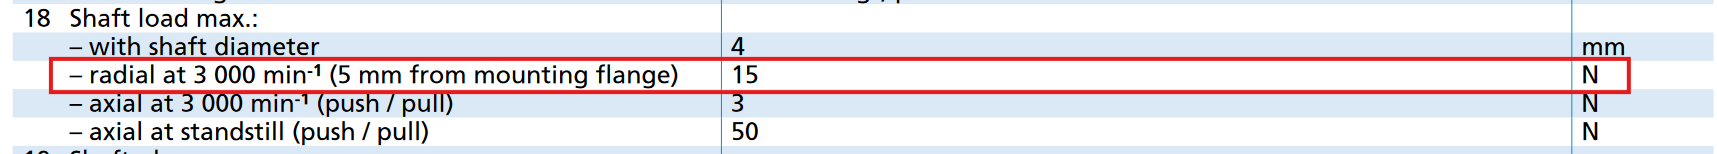

clc
clear

% inputs
m_mot = 66.7 * 1e-3;   % kg

m_mot = 0.0667

%a_max = 0.4;              % m/s²

g = 9.81;                 % m/s²
a_max =3*g;              % m/s²  under the effect of 3g disturbances 

c = 16.8 / 2;             % mm
l = 46.1;                 % mm [unused]
d_e1 = 9.5;               % mm
d_i1 = 7;                 % mm
d_2 = 6;                  % mm

E_1 = 71.7 * 1e3;        % MPa
E_2 = 193 * 1e3;         % MPa

P_mot_dat = 15;           % N
b_mot_dat = 5;            % mm

% calc
J_x1 = pi/64 * (d_e1^2 - d_i1^2);          % mm^4
J_x2 = pi/64 * (d_2^2);                    % mm^4

P = m_mot * (a_max+g);                                % N
M_x = P*c;                                        % N mm
M_x2 = (E_2*J_x2) / (E_1*J_x1 + E_2*J_x2) * M_x   % N mm

M_x2 = 15.4210

M_crit = P_mot_dat * b_mot_dat                    % N mm

M_crit = 75